**Ionic Current Model of Bipolar Cells**

Set constants

% Timespan. sec.
tspan = [0, 5];

% Hyperpolarizing current injections. pA.
hyper_injections = [-30, -20, -10];
num_hyper = length(hyper_injections);

% Depolarizing current injections. pA.
depolar_injections = [30, 20, 10];
num_de = length(depolar_injections);

*Compute voltage (hyperpolarizing)*

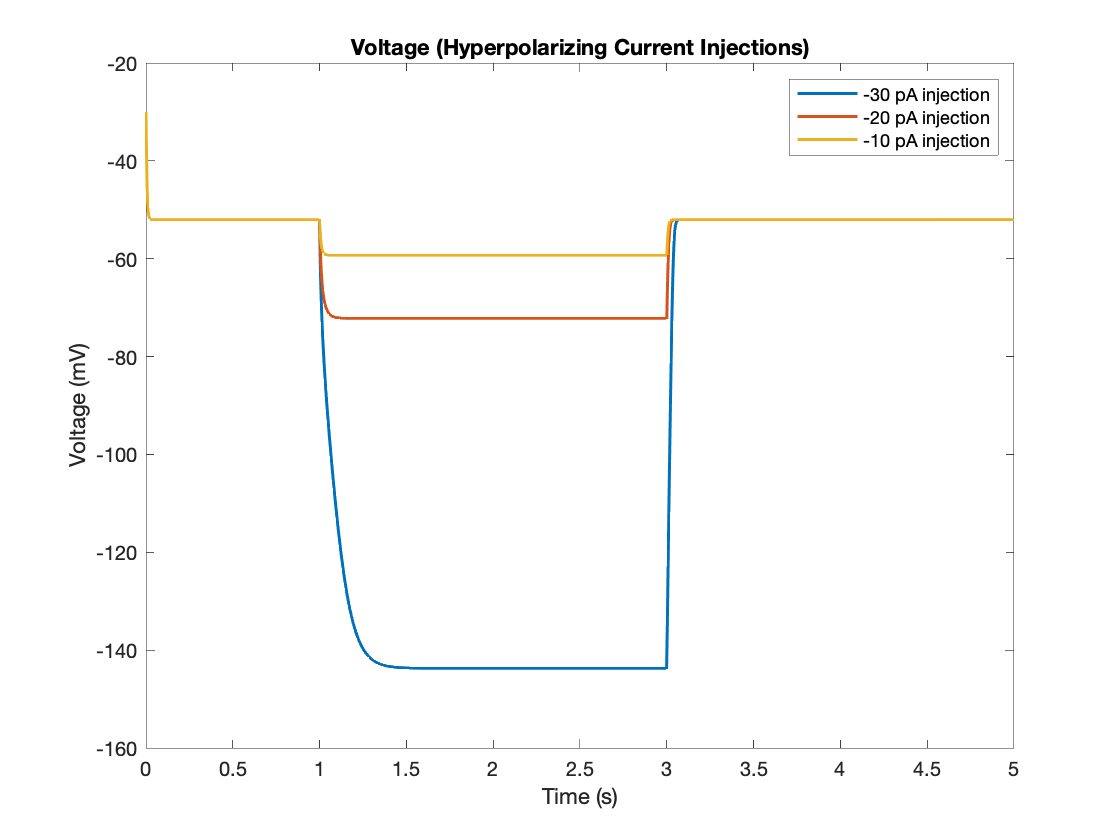

% Compute voltages.
[t_30, res_30] = calcV(tspan,hyper_injections(1));
V_30 = res_30(:,5);
[t_20, res_20] = calcV(tspan,hyper_injections(2));
V_20 = res_20(:,5);
[t_10, res_10] = calcV(tspan,hyper_injections(3));
V_10 = res_10(:,5);

% Interpolation to account for different sizes.
maxLen = max([length(t_30), length(t_20), length(t_10)]);
newT = linspace(tspan(1), tspan(2), maxLen);
newV_30 = interp1(t_30, V_30, newT);
newV_20 = interp1(t_20, V_20, newT);
newV_10 = interp1(t_10, V_10, newT);

% Plot the results.
plot(newT, newV_30, newT, newV_20, newT, newV_10, 'LineWidth', 1.5)
title('Voltage (Hyperpolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Compute voltage (depolarizing)*

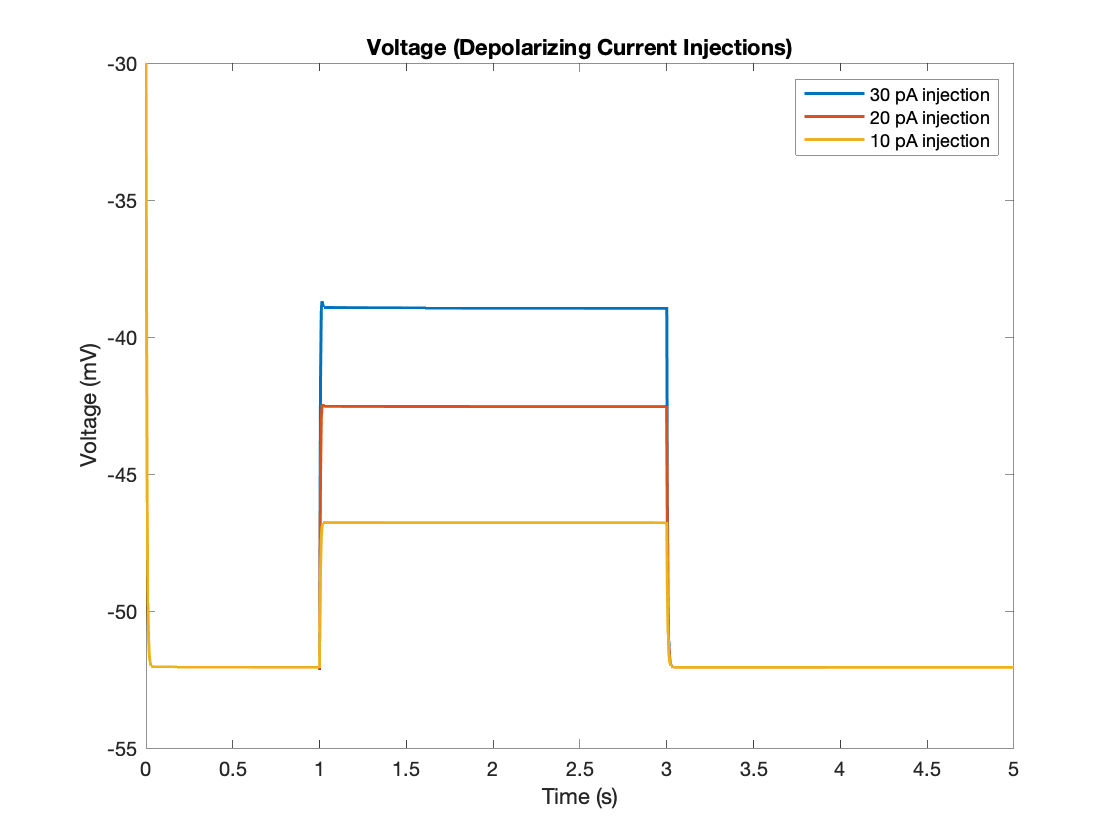

% Compute voltages.
[t30, res30] = calcV(tspan,depolar_injections(1));
V30 = res30(:,5);
[t20, res20] = calcV(tspan,depolar_injections(2));
V20 = res20(:,5);
[t10, res10] = calcV(tspan,depolar_injections(3));
V10 = res10(:,5);

% Interpolation to account for different sizes.
newV30 = interp1(t30, V30, newT);
newV20 = interp1(t20, V20, newT);
newV10 = interp1(t10, V10, newT);

% Plot the results.
plot(newT, newV30, newT, newV20, newT, newV10, 'LineWidth', 1.5)
title('Voltage (Depolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')
legend('30 pA injection','20 pA injection', '10 pA injection')

*Calcium current*

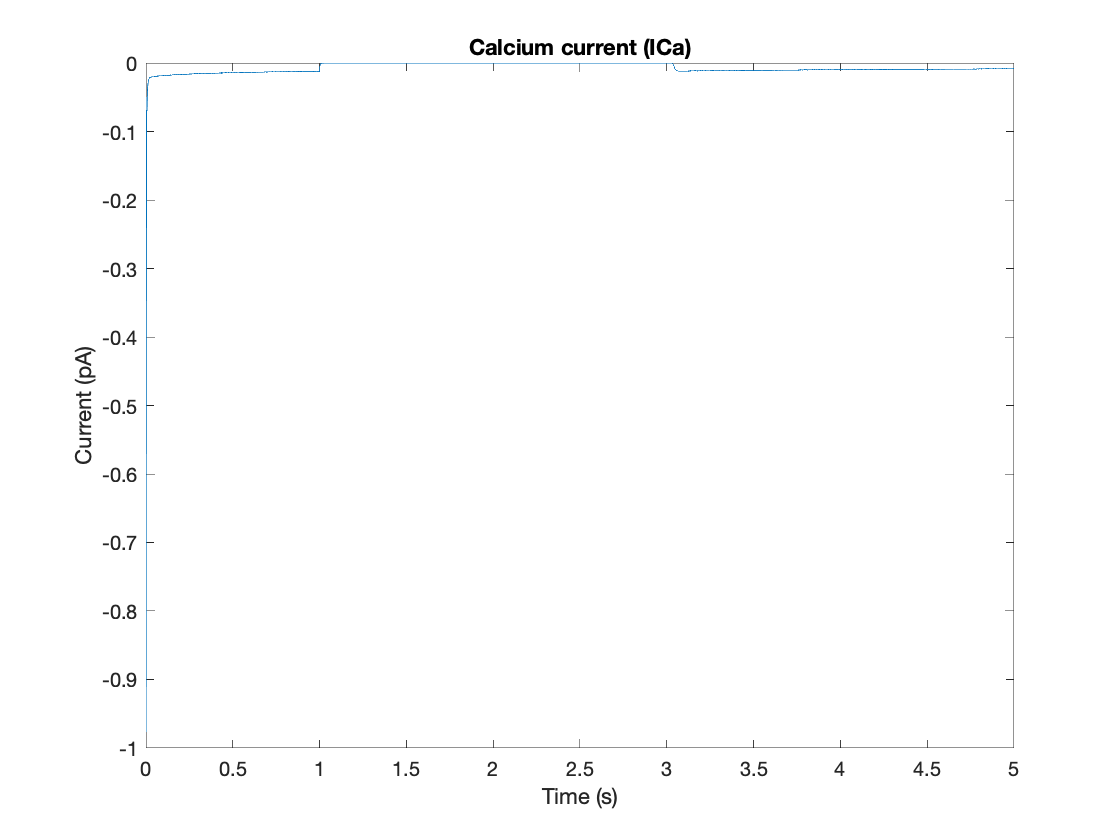

mCa = res(:,3);
ICa = calcICa(t, mCa, Cas, V);
plot(t, ICa)

title('Calcium current (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Calcium-dependent K current*

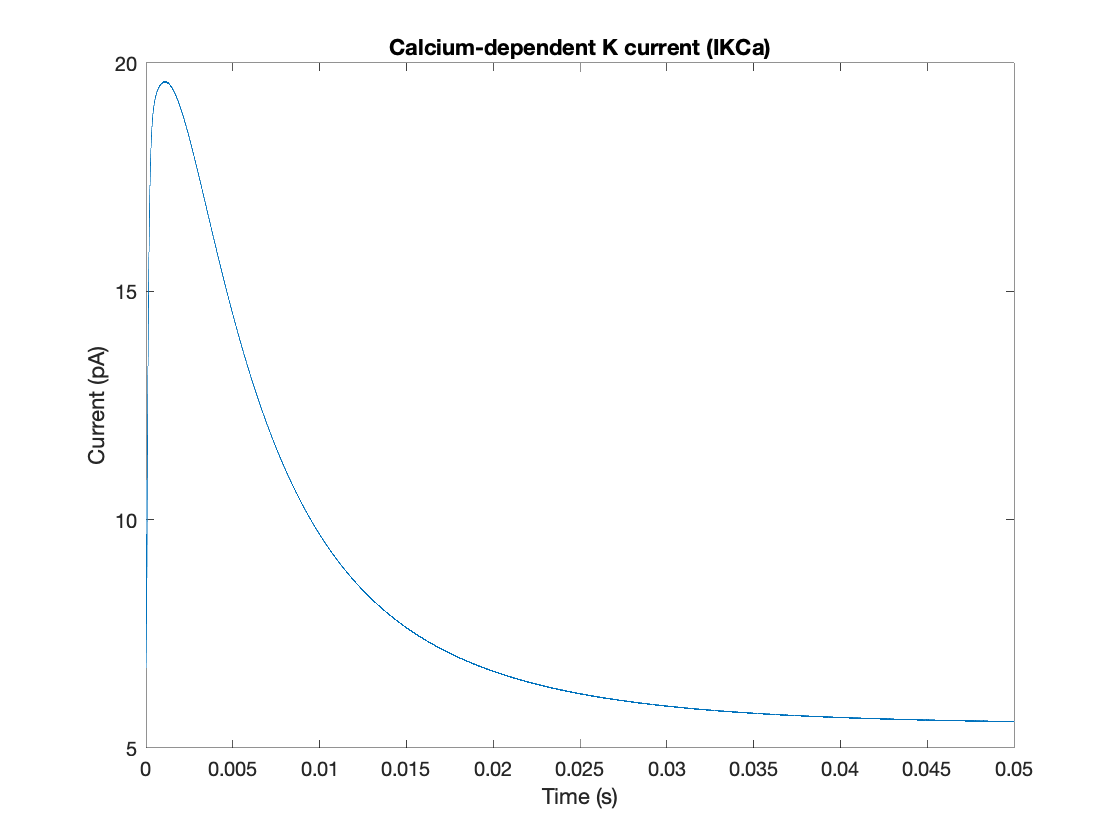

mKc = res(:,4);
IKCa = calcIKCa(t, mKc, Cas, V);
plot(t, IKCa)

title('Calcium-dependent K current (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Delayed rectifying potassium current*

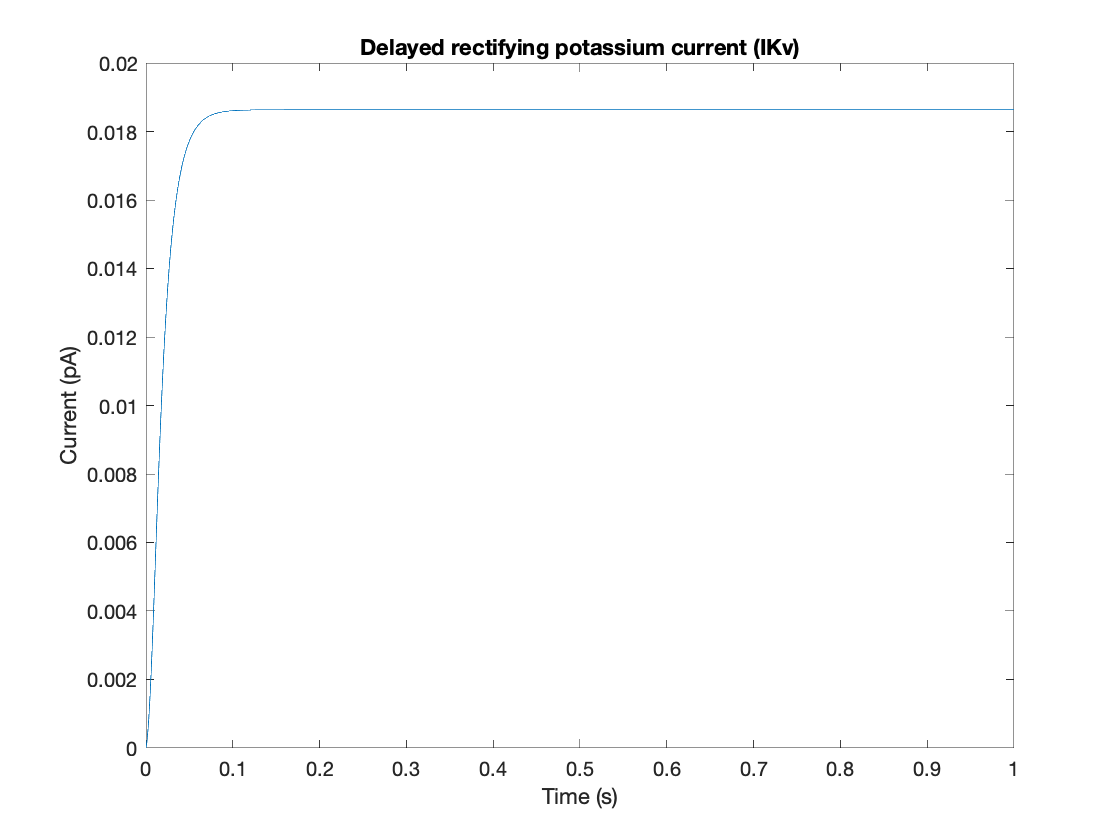

mKv = res(:,1);
hKv = res(:,2);
IKv = calcIKv(t, mKv, hKv, V);
plot(t, IKv)

title('Delayed rectifying potassium current (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Hyperpolarization activated current*

O1 = res(:,8);
O2 = res(:,9);
O3 = res(:,10);
Ih = calcIh(t, O1, O2, O3, V);

Ih =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


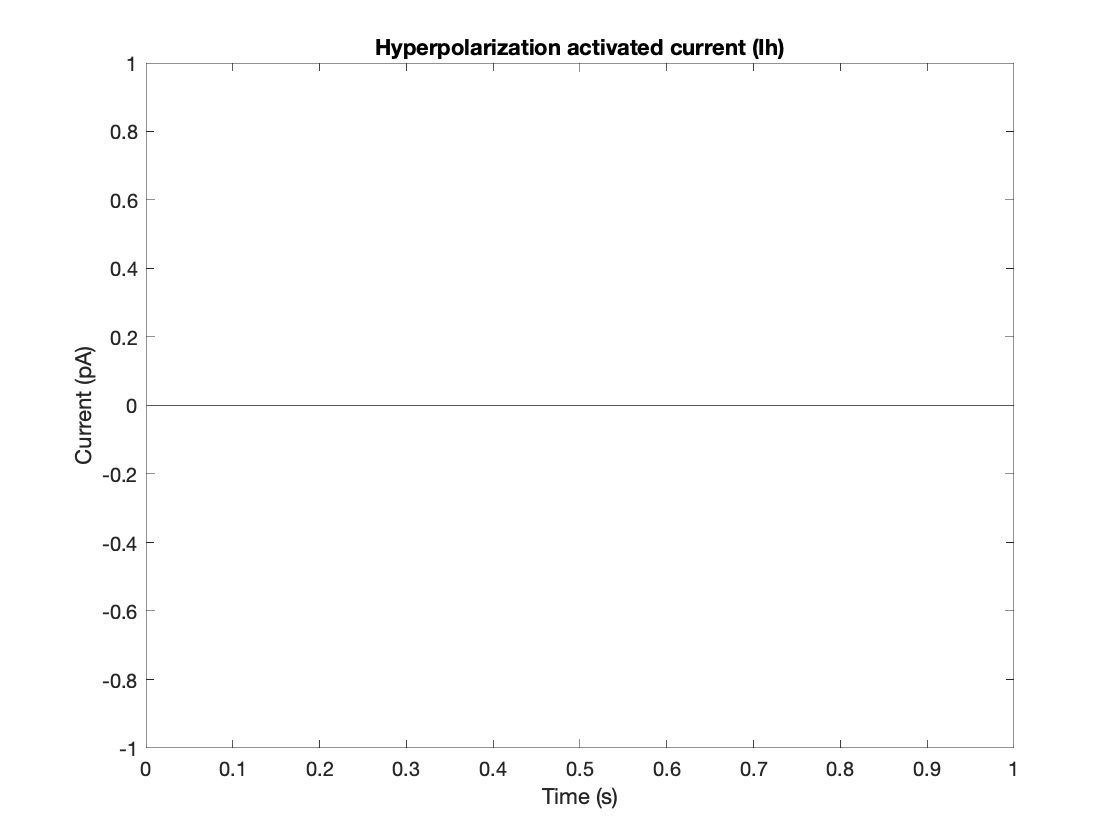

plot(t, Ih)

title('Hyperpolarization activated current (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Leakage current*

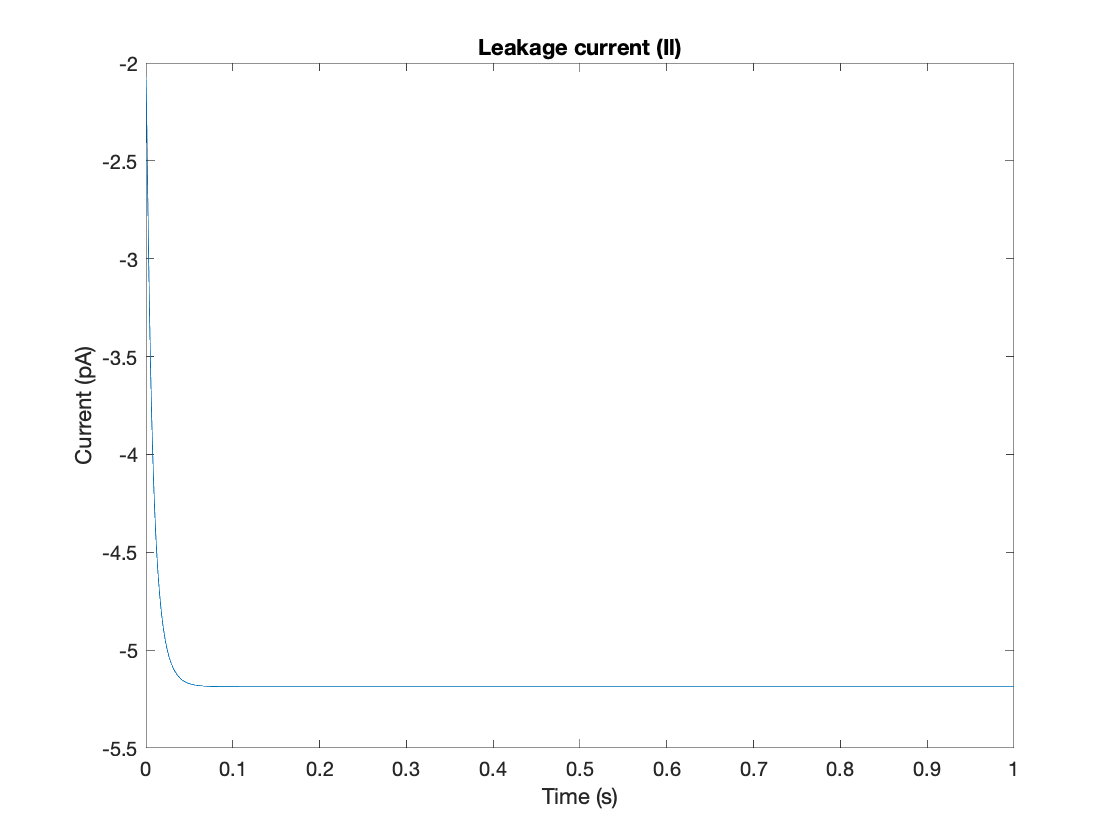

Il = calcIl(V);
plot(t, Il)

title('Leakage current (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Total ionic current*

% totalI = IKv+Ih+ICa+IKCa+Il+IA; % add injection current too

Requested 89288573x89288573 (59399375.8GB) array exceeds maximum array size preference. Creation of arrays greater than this limit may take a long time and cause MATLAB to become unresponsive. See array size limit or preference panel for more information.

% plot(t, totalI)
% 
% title('Total ionic current')
% xlabel('Time (s)')
% ylabel('Current (pA)')